# ACW - Michael Hughes - 563267

%Initialise
clear; close all; clc;

%Load Image
[file,path] = uigetfile({'*.jpg';'*.png';'*.tif'},"Select an image of starfish","starfish.jpg","MultiSelect","off");
if isequal(file,0)
   disp('User selected Cancel');
   return
else
   disp(['User selected ', fullfile(path,file)]);
end

User selected D:\mikey\Documents\GitHub\Computer-Vision-ACW\Images\starfish.jpg


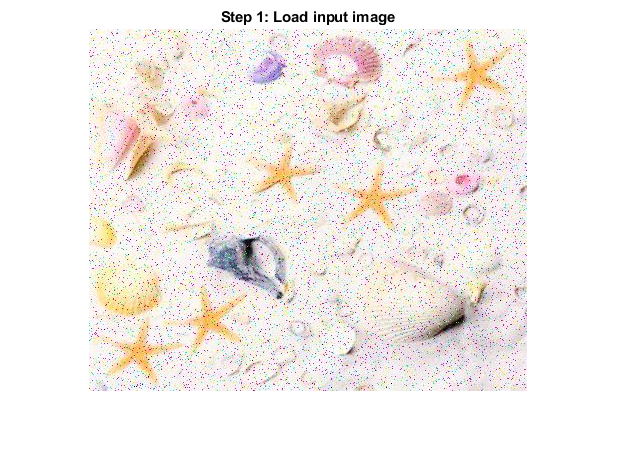




Img = imread(fullfile(path,file));
imshow(Img), title('Step 1: Load input image');

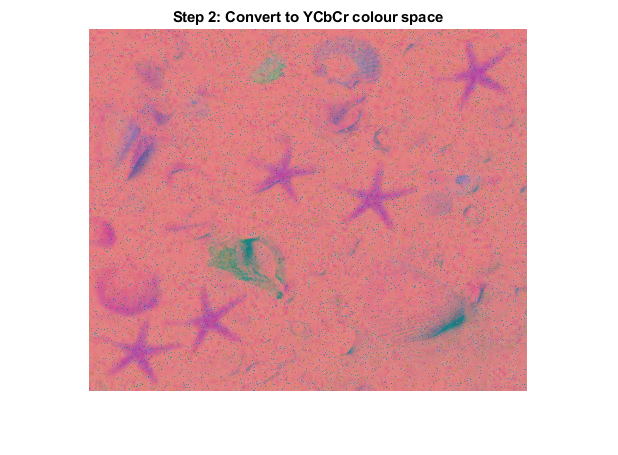

%Convert to different Colour Space
ycbcrimg = rgb2ycbcr(Img);
imshow(ycbcrimg), title('Step 2: Convert to YCbCr colour space');

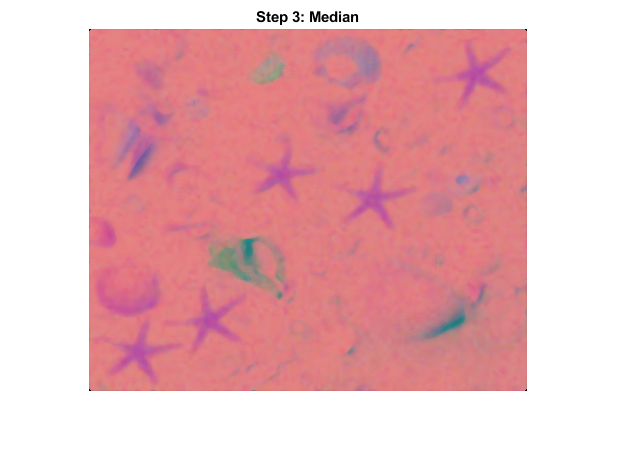

%Filters

%median
img_median = ycbcrimg;
for c = 1 : 3
    img_median(:, :, c) = medfilt2(ycbcrimg(:, :, c), [5, 5]);
end
imshow(img_median)
title('Step 3: Median')

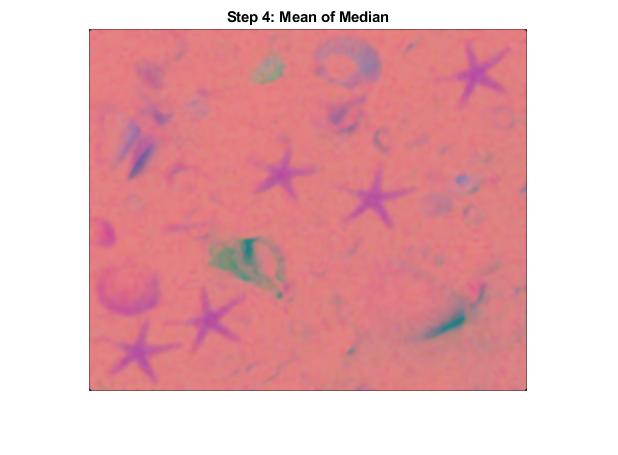


% 3x3 mean kernel
kernel = ones(3,3)/9; %1/9* ones(2) 

img_mean = img_median;
for c=1:3
     img_mean(:, :, c) = conv2(img_median(:, :, c),kernel,"same");
%J = conv2(I, kernel, 'same');
end
% Convolve keeping size of I
imshow(img_mean)
title('Step 4: Mean of Median')

% % % 3x3 mean kernel
% % kernel =1/3* ones(2);
% % img_mean = Img2;
% % for c=1:3
% %      img_mean(:, :, c) = conv2(Img2(:, :, c),kernel,"same");
% % %J = conv2(I, kernel, 'same');
% % end
% %Convolve keeping size of I
% img_mean = Img2
% for c = 1:3
%     img_mean(:,:,c) = filter2(fspecial('average',3),Img2(:,:,c))/255;
% end
% % 
% % h = 1/3*ones(3,1);
% % H = h*h';
% % % im be your image
% % img_mean = filter2(H,img_median);
% 
% 
% 
% img_median = img_mean;
% for c = 1 : 3
%     img_median(:, :, c) = medfilt2(img_mean(:, :, c), [3, 3]);
% end
% imshow(img_median), title('Step 3: Median Filter')

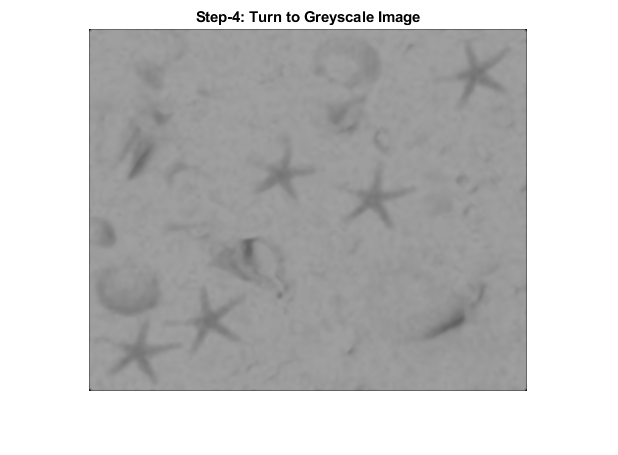

img_enhance = rgb2gray((img_mean));
imshow(img_enhance);
title('Step-4: Turn to Greyscale Image');

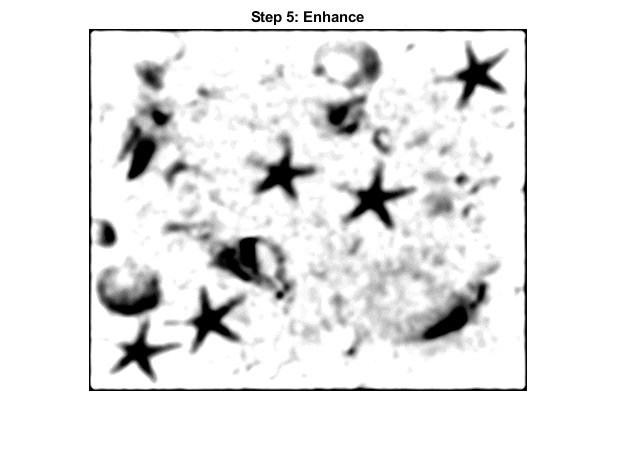

I4=img_enhance;
I4 = imgaussfilt(I4,2);
I4 = imadjust(I4);


I4 = imsharpen(I4,'Radius',40,'amount',0.8,'threshold',0);

imshow(I4), title('Step 5: Enhance');

T = graythresh(I4)

T = 0.5843

BW = imbinarize(I4,T);
binaryImage = imcomplement(BW)

binaryImage = 362×438 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

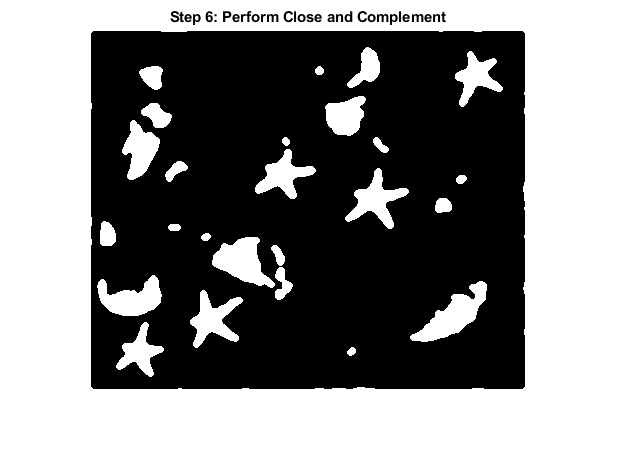

%imshow(binaryImage)
%binaryImage = ~binaryImage;
%imshow(binaryImage)

% SE = strel( ...
%        [0  0  0  1  0  0  0 ; 
%         0  1  1  1  1  1  0 ; 
%         0  1  1  1  1  1  0 ; 
%         1  1  1  1  1  1  1 ; 
%         0  1  1  1  1  1  0 ; 
%         0  1  1  1  1  1  0 ; 
%         0  0  0  1  0  0  0 ])
SE=strel('disk',4);
BW2 = bwareaopen(BW,200) ;
J = imclose(BW2,SE);
%SE = strel('rectangle',[2 5])
%J = imerode(binaryImage,SE)
FilteredImage=imcomplement(J);
imshow(FilteredImage),title('Step 6: Perform Close and Complement')

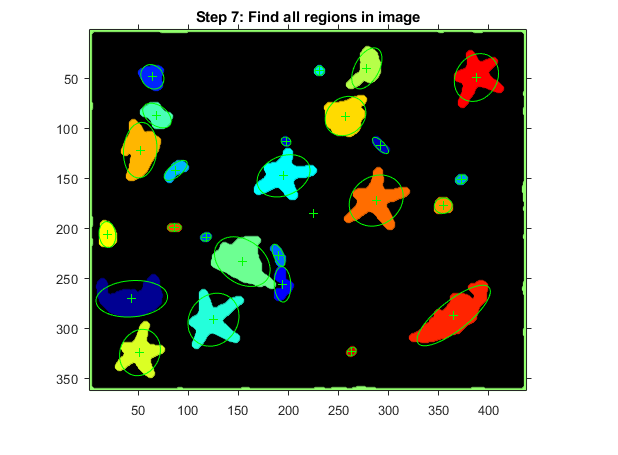

% Section 3: MSER Algorithm
% Built in function
% Detect and store regions.

% Which one should you use? Do we need ConnComp here?
[Regions, ConnComp] = detectMSERFeatures(FilteredImage);
Regions = detectMSERFeatures(FilteredImage);

% Display the centroids and axes of detected regions.
%imshow(FilteredImage); hold on; plot(Regions); hold off;
[Nregions, ~] = size( Regions );
if (Nregions > 100) 
    Nregions = 100;
end
imshow(FilteredImage); hold on;
plot(Regions(1:Nregions),'showPixelList', true),axis on,title("Step 7: Find all regions in image");
hold off;



% Using Results of MSER to find objects via regionprops etc.
% Use this section for five_objects.jpg or four_objects.jpg
% properties = regionprops(, 'all'); % uncomment if all metrics required
mserStats = regionprops(ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image','Extrema','Circularity','Area','Perimeter');
properties_table = regionprops('table',ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image','Extrema','Circularity','Area','Perimeter');
% show table
disp('Step 8: Get region props')

Step 8: Get region props


properties_table;
properties_table = sortrows(properties_table,'BoundingBox')

properties_table = 26×9 table
    Area              BoundingBox               Eccentricity    Circularity          Image            Extrema       Solidity     Extent     Perimeter
    ____    ________________________________    ____________    ___________    _________________    ____________    ________    ________    _________

    1796      1.5      1.5      436      360        0.501        0.0093232     {360×436 logical}    {8×2 double}    0.011442    0.011442     1555.9  
    1558      8.5    246.5       65       41      0.86306          0.50176     { 41×65  logical}    {8×2 double}     0.71731     0.58462     197.53  
     329     11.5    192.5       16       25      0.77081      

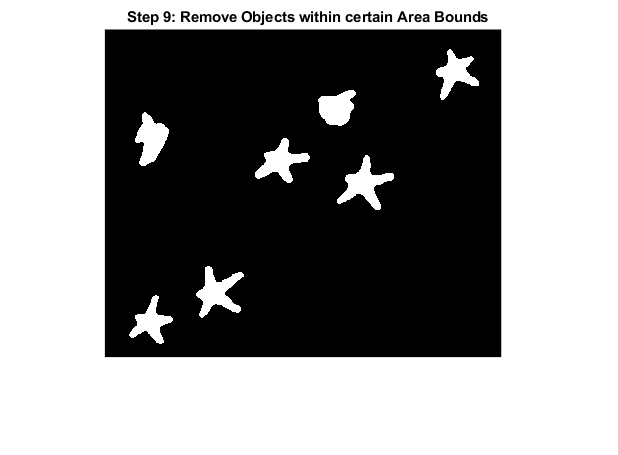

CC = bwconncomp(FilteredImage, 4);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);
BW5 = ismember(L, find([S.Area] >= 700 & [S.Area]<= 1550));
figure; hold on
imshow(BW5),title('Step 9: Remove Objects within certain Area Bounds')

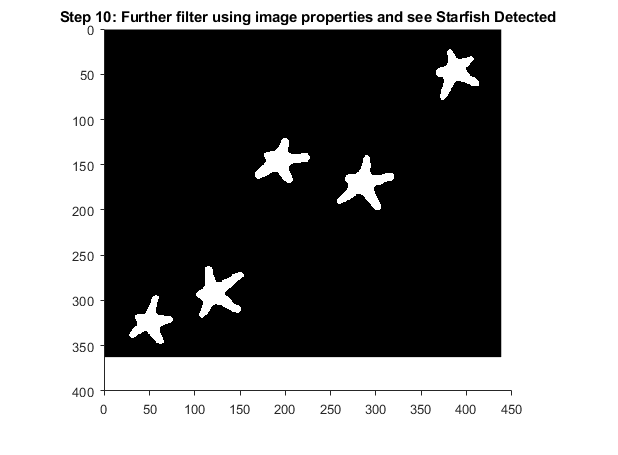

% selecting five point star
BW_out = BW5;
% Filter image based on image properties.

BW_out = bwpropfilt(BW_out, 'Eccentricity', [0.1, 0.75]);
BW_out = bwpropfilt(BW_out, 'Extent', [0.1, 0.58]);
BW_out = bwpropfilt(BW_out, 'Solidity', [0.1, 0.808]);
% Get rid of blobs with low circularity.

%0.87
%BW_out = bwpropfilt(BW_out, 'Circularity', [0, 0.7]);
figure; hold on
imshow(BW_out); title('Step 10: Further filter using image properties and see Starfish Detected');axis on; hold off;

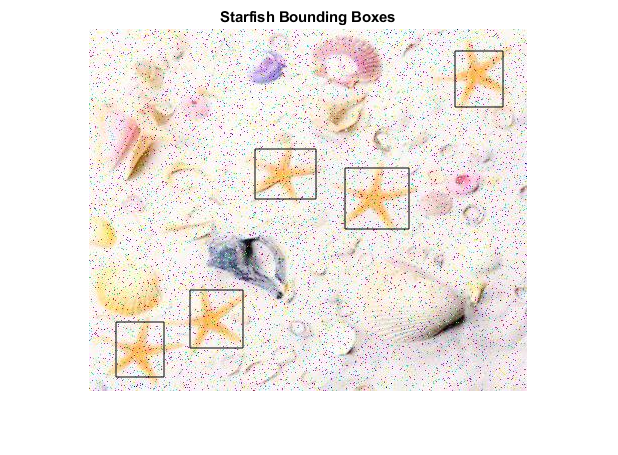



starfish = regionprops(BW_out, 'BoundingBox');
imshow(Img),title('Starfish Bounding Boxes'); hold on;
hold on
for k = 1 : length(starfish)
    thisBB = starfish(k).BoundingBox;
    hold on;
    rectangle('Position', thisBB);
end

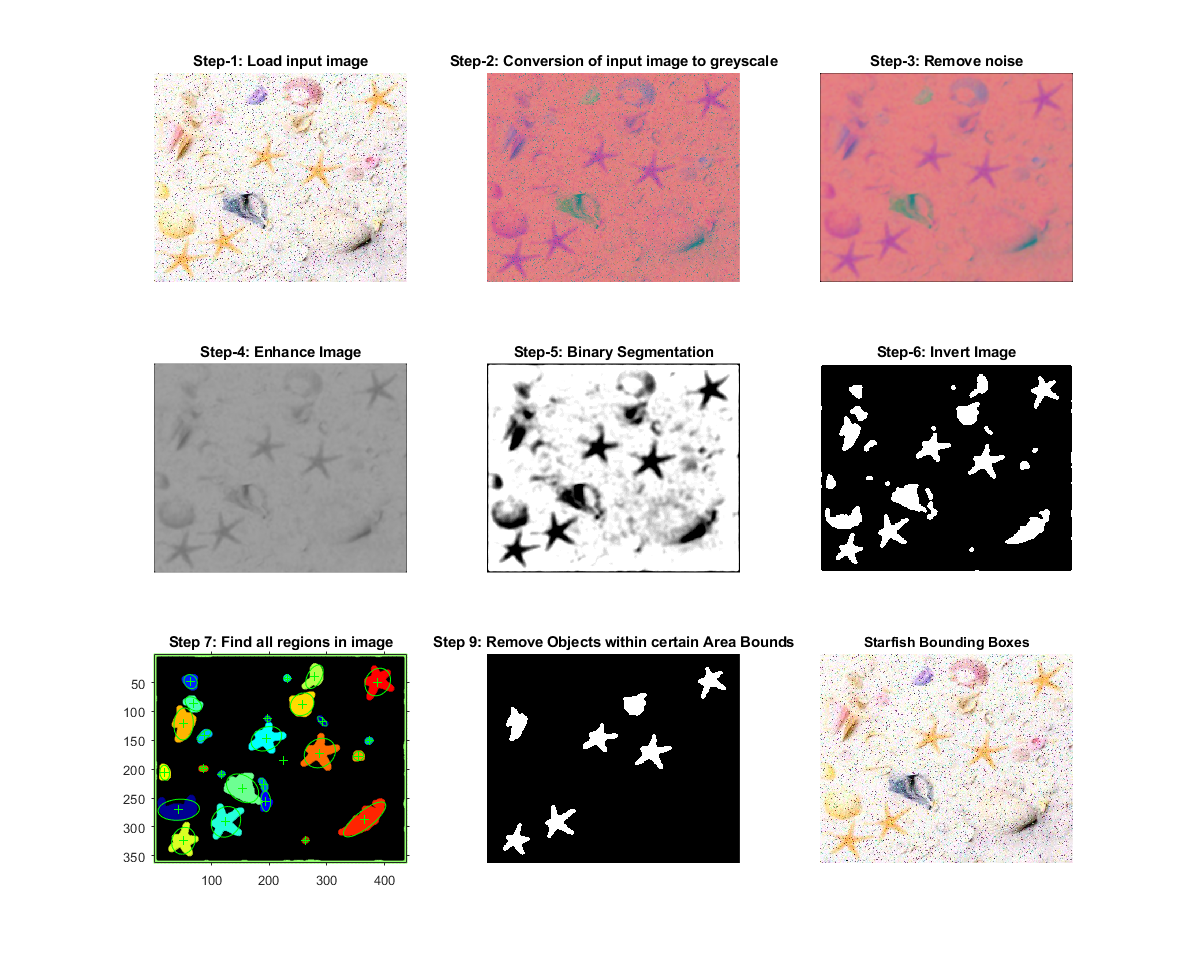


figure, 
subplot(3,3,1),  imshow(Img), title('Step-1: Load input image');
subplot(3,3,2),  imshow(ycbcrimg), title ('Step-2: Conversion of input image to greyscale');
subplot(3,3,3), imshow(img_mean),title('Step-3: Remove noise');
subplot(3,3,4),  imshow(img_enhance),title('Step-4: Enhance Image');
subplot(3,3,5),  imshow(I4),title('Step-5: Binary Segmentation');
subplot(3,3,6),  imshow(FilteredImage), title('Step-6: Invert Image');
subplot(3,3,7), imshow(FilteredImage); hold on;
plot(Regions(1:Nregions),'showPixelList', true),axis on,title("Step 7: Find all regions in image");
hold off;
subplot(3,3,8),  imshow(BW5),title('Step 9: Remove Objects within certain Area Bounds');
subplot(3,3,9),  imshow(Img),title('Starfish Bounding Boxes'); hold on;
truesize;





fprintf("Starfish: " + length(starfish))

Starfish: 5